# Strength of Materials Approach

clc;clear;
syms Vf
Vf_val = linspace(0,1,101);

%fiber
E_f = 80;
G_f = 33.33;
v_f = 0.2;
a_f = 4.9 * 1e-6;

S_f = [1/E_f, -v_f/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, 1/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, -v_f/E_f, 1/E_f, 0, 0, 0;
       0, 0, 0, 1/G_f, 0, 0;
       0, 0, 0, 0, 1/G_f, 0;
       0, 0, 0, 0, 0, 1/G_f;];
C_f = inv(S_f);

%matrix
E_m = 4.2;
v_m = 0.34;
a_m = 45 * 1e-6;
G_m = E_m/(2*(1+v_m));

S_m = [1/E_m, -v_m/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, 1/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, -v_m/E_m, 1/E_m, 0, 0, 0;
       0, 0, 0, 1/G_m, 0, 0;
       0, 0, 0, 0, 1/G_m, 0;
       0, 0, 0, 0, 0, 1/G_m;];
C_m = inv(S_m);

# Strength of materials approach

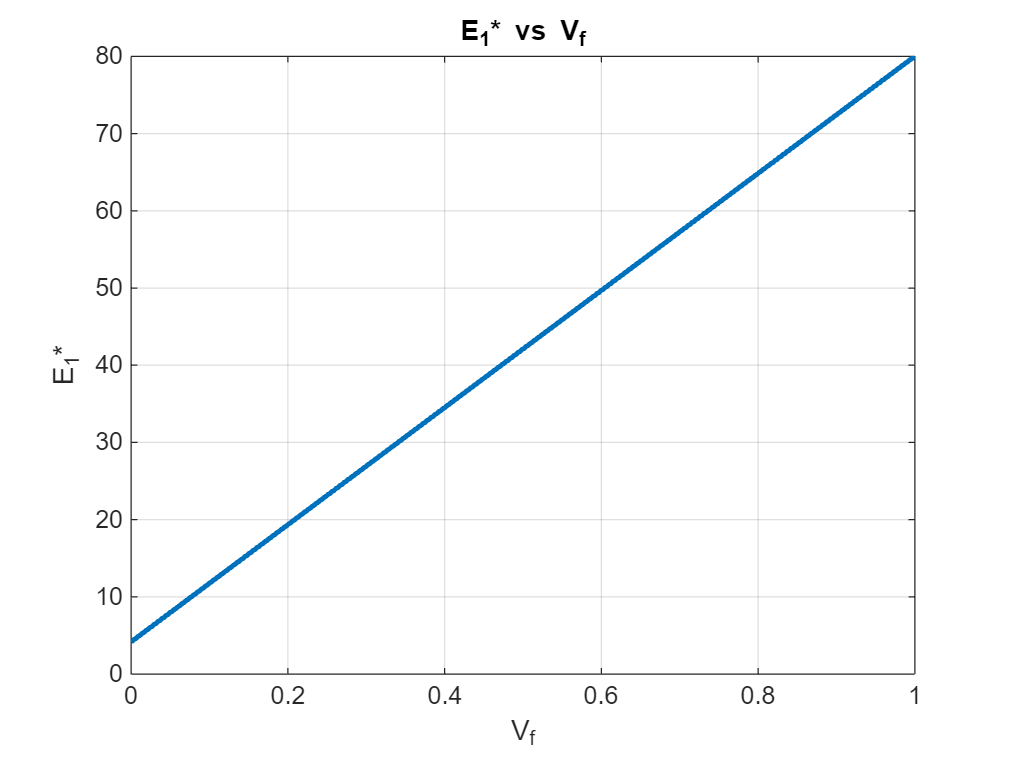

%axial youngs modulus
E1_c = E_f*Vf + E_m*(1-Vf);
E1_c_val = subs(E1_c,Vf_val);

%axial poisson's ratio
v12_c = v_f*Vf + v_m*(1-Vf);
v12_c = subs(v12_c,Vf_val);

%direction 2 youngs modulus
E2_c = E_f*E_m / (E_m*Vf + E_f*(1-Vf));
E2_c = subs(E2_c,Vf_val);

%axial shear modulus
G12_c = G_f*G_m / (G_m*Vf + G_f*(1-Vf));
G12_c = subs(G12_c,Vf_val);

%thermal coeff in direction 1
a1_c = ((a_f*E_f - a_m*E_m)*Vf + a_m*E_m) / ((E_f - E_m)*Vf + E_m);
a1_c = subs(a1_c,Vf_val);

%thermal coeff in direction 2
a2_c = a_f*Vf + a_m*(1-Vf) + ((E_f*v_m - E_m*v_f) / (E1_c)) * (a_m - a_f) * (1-Vf) * Vf;
a2_c = subs(a2_c,Vf_val);

%plot
% Axial Young's modulus
figure(1)
plot(Vf_val, E1_c_val, 'LineWidth', 2);
grid on;
title('E_1* vs V_f');
xlabel('V_f'); ylabel('E_1*');

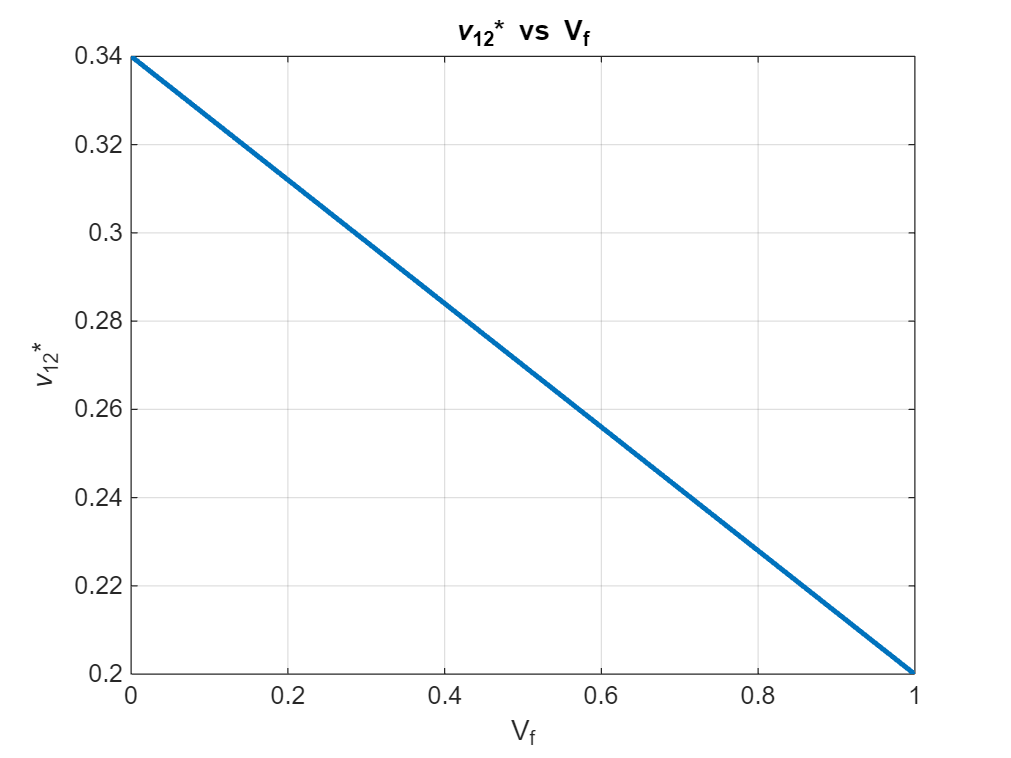


% Axial Poisson's ratio
figure(2)
plot(Vf_val, v12_c, 'LineWidth', 2);
grid on;
title('\nu_{12}* vs V_f');
xlabel('V_f'); ylabel('\nu_{12}*');

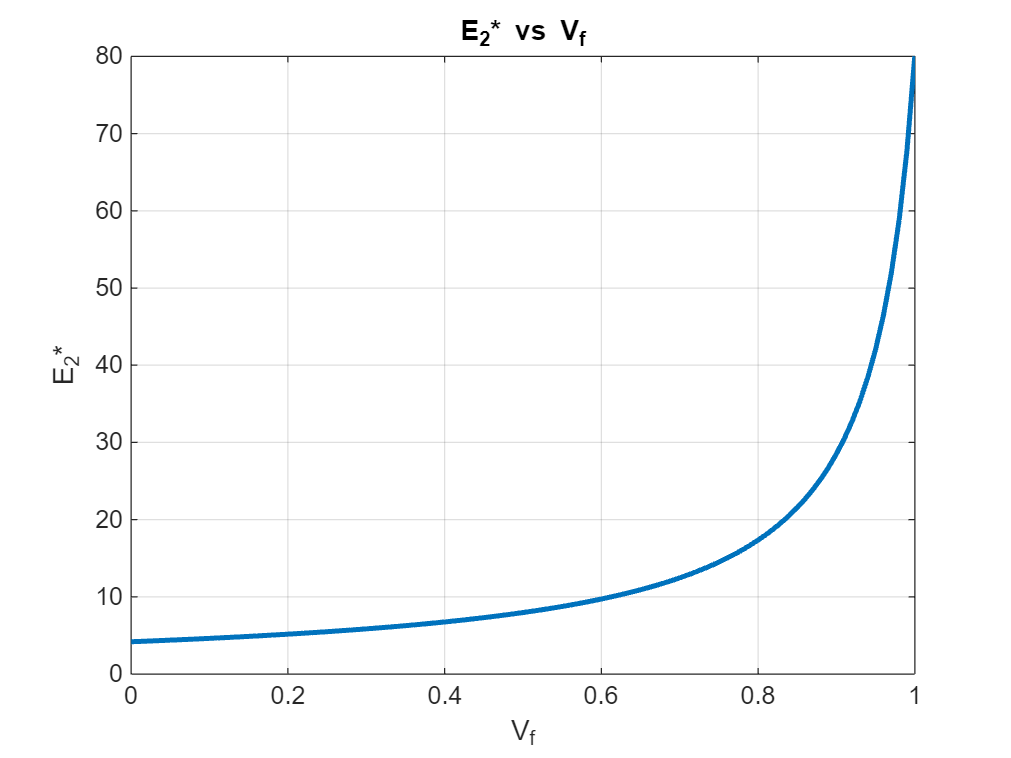


% Transverse Young's modulus
figure(3)
plot(Vf_val, E2_c, 'LineWidth', 2);
grid on;
title('E_2* vs V_f');
xlabel('V_f'); ylabel('E_2*');

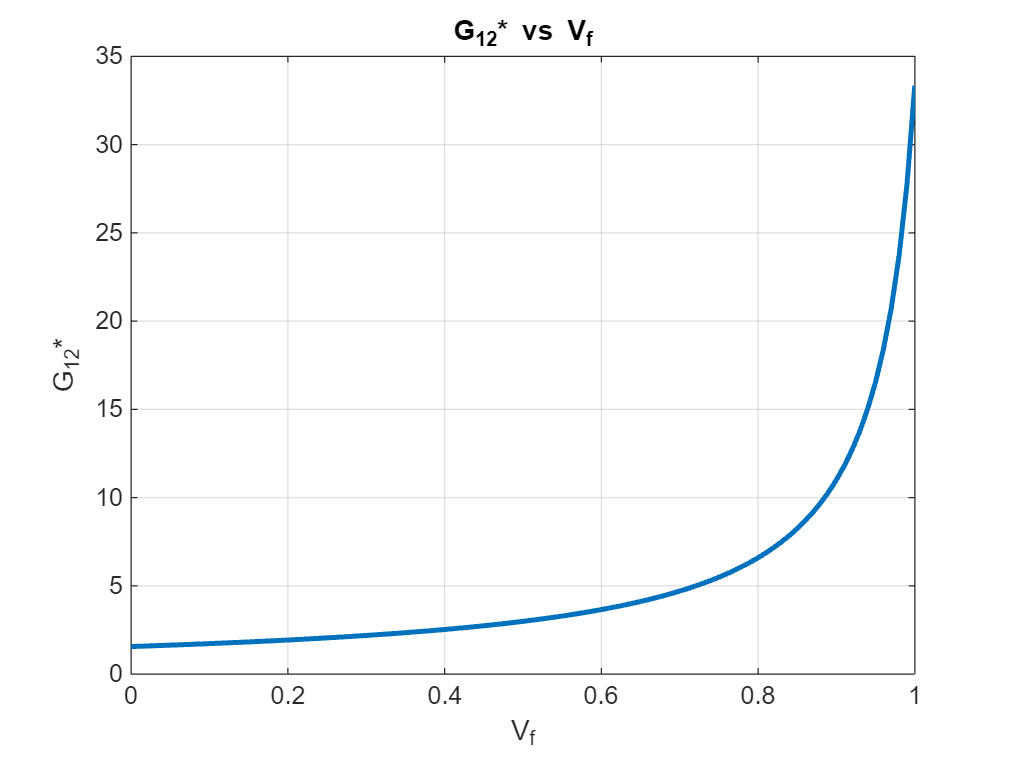


% Axial shear modulus
figure(4)
plot(Vf_val, G12_c, 'LineWidth', 2);
grid on;
title('G_{12}* vs V_f');
xlabel('V_f'); ylabel('G_{12}*');

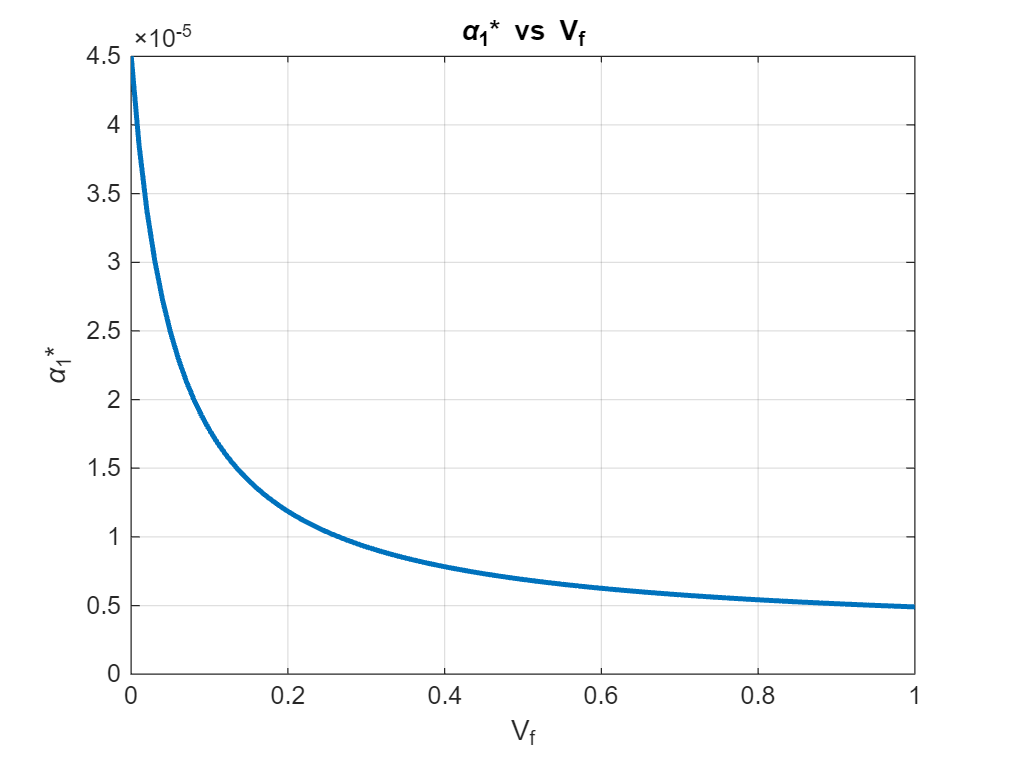


% Thermal coefficient in direction 1
figure(5)
plot(Vf_val, a1_c, 'LineWidth', 2);
grid on;
xlabel('V_f');
ylabel('\alpha_1*');
title('\alpha_1* vs V_f');

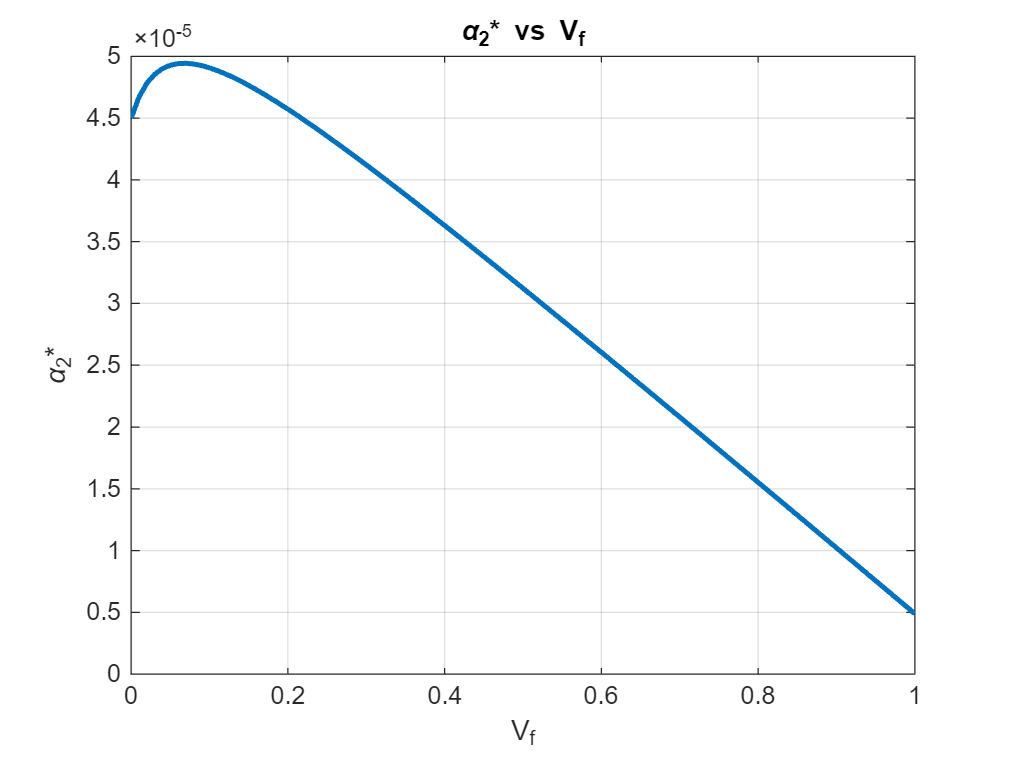


% Thermal coefficient in direction 2
figure(6)
plot(Vf_val, a2_c, 'LineWidth', 2);
grid on;
xlabel('V_f');
ylabel('\alpha_2*');
title('\alpha_2* vs V_f');